clc; clear;
% %obj = visa('ni',"USB0::0x0699::0x0401::C002176::0")
% rsrc = "USB0::0x0699::0x0401::C002176::INSTR"
% visausb = visadev(rsrc)
% %fopen(obj)
% %record(obj,"on")
% %visastatus(visausb)
% %visausb.write()
% visausb.get("SerialNumber")
% 
% groupObj = visausb.get('Waveform');
% [Y,X] = invoke(groupObj, 'readwaveform', channel1');
% plot(Y,X)
addr = "USB0::0x0699::0x0421::C026909::0::INSTR";%'USB0::0x0699::0x03C7::C020471::INSTR';%'USB0::0x0699::0x03C7::C020477::0::INSTR';
% Create a VISA-USB object.
%interfaceObj = instrfind('Type', 'visa-usb', 'RsrcName', 'USB0::0x0699::0x0401::C002176::0::INSTR', 'Tag', '');
interfaceObj = instrfind('Type', 'visa-usb', 'RsrcName', addr, 'Tag', '');

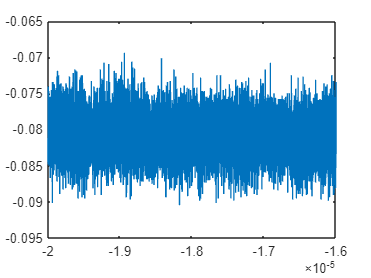

% Create the VISA-USB object if it does not exist
% otherwise use the object that was found.
if isempty(interfaceObj)
    interfaceObj = visa('NI', addr);
else
    fclose(interfaceObj);
    interfaceObj = interfaceObj(1);
end

%query(interfaceObj,"ACQuire:MAXSamplerate?")
% format longG
% t = now;
% d = datetime(t,'ConvertFrom','datenum');
% d_str = string(d);
% 
% d_str(find(~isspace(d_str)))
% 
% mkdir(strcat("radar\scope\test-", d_str));

% Create a device object. 
deviceObj = icdevice('tektronix_mso4104.mdd', interfaceObj);
%deviceObj = icdevice('tektronix_tds2024.mdd', interfaceObj);

% Connect device object to hardware.
connect(deviceObj);

% Execute device object function(s).
groupObj = get(deviceObj, 'Waveform');
[Y,X] = invoke(groupObj, 'readwaveform', 'channel1');
%[Y1,X1] = invoke(groupObj, 'readwaveform', 'channel2');
figure;
plot(X,Y);

%figure;
%plot(X1,Y1);